**BE MATLAB VFEA**

**FISA 2A**

*=> GROUP : *

- *BABIN-RIBY Hugo*

- *BUFFARD-MICELI Eliot*

clear all;
%VARIABLES INIT
E = 7*10^10; % Pa / YOUNG MODULE 
rho = 2750; % kg/m3 / Volumic mass
L = 340; % mm / total lenght of considered rod
b = 22; % mm / side lenght of section
t = 2; % mm / side lenght of section
S = b * t; % mm^2 / Section
I =  (b*t^3)/12; % mm^4 / quadratic moment

%Number of elements, to modify depending on the case
nel = 10; % nel
nn = nel + 1; % nombre noeuds = ndegliberté
l0 = L / nel; % lenght of an element
kmax = L/l0; % kmax
c0 = sqrt(E/rho); % célérité dans la matière

% Mass and stiffness matrix of one element.
mc = [2 1 ; 1 2] * (rho*S*l0/6);
md = [3 0 ; 0 3] * (rho*S*l0/6);
k = [1 -1 ; -1 1] * (E*S/l0);

%ASSEMBLE MATRIXES

% make M mass matrix
M = zeros(nn,nn);
%assamble M
for el = 1:nn-1; % boucle sur les éléments
    M(el:el+1,el:el+1) = mc + M(el:el+1,el:el+1);
end
disp("M mass matrix :")

M mass matrix :


disp(M / (rho*S*l0/6)); %display only coeficients in order to check if is good

     2     1     0     0     0     0     0     0     0     0     0
     1     4     1     0     0     0     0     0     0     0     0
     0     1     4     1     0     0     0     0     0     0     0
     0     0     1     4     1     0     0     0     0     0     0
     0     0     0     1     4     1     0     0     0     0     0
     0     0     0     0     1     4     1     0     0     0     0
     0     0     0     0     0     1     4     1     0     0     0
     0     0     0     0     0     0     1     4     1     0     0
     0     0     0     0     0     0     0     1     4     1     0
     0     0     0     0     0     0     0     0     1     4     1
     0     0     0     0     0     0     0     0     0     1     2





%make K stiffness matrix 
K = zeros(nn,nn);
%assamble K
for el = 1:nn-1;
    K(el:el+1,el:el+1) = k + K(el:el+1,el:el+1);
end
disp("K stiffness matrix :")

K stiffness matrix :


disp(K / (E*S/l0)); %display only coeficients in order to check if is good

     1    -1     0     0     0     0     0     0     0     0     0
    -1     2    -1     0     0     0     0     0     0     0     0
     0    -1     2    -1     0     0     0     0     0     0     0
     0     0    -1     2    -1     0     0     0     0     0     0
     0     0     0    -1     2    -1     0     0     0     0     0
     0     0     0     0    -1     2    -1     0     0     0     0
     0     0     0     0     0    -1     2    -1     0     0     0
     0     0     0     0     0     0    -1     2    -1     0     0
     0     0     0     0     0     0     0    -1     2    -1     0
     0     0     0     0     0     0     0     0    -1     2    -1
     0     0     0     0     0     0     0     0     0    -1     1




% We also make an Md matrix, using the diagonal mass matrix for furthuer
% comparaisons
Md = zeros(nn,nn);
%assamble M
for el = 1:nn-1; % boucle sur les éléments
    Md(el:el+1,el:el+1) = md + Md(el:el+1,el:el+1);
end

disp("Md diagonal mass matrix (for comparaison at the end) :")

Md diagonal mass matrix (for comparaison at the end) :


disp(Md / (rho*S*l0/6)); %display only coeficients in order to check if is good

     3     0     0     0     0     0     0     0     0     0     0
     0     6     0     0     0     0     0     0     0     0     0
     0     0     6     0     0     0     0     0     0     0     0
     0     0     0     6     0     0     0     0     0     0     0
     0     0     0     0     6     0     0     0     0     0     0
     0     0     0     0     0     6     0     0     0     0     0
     0     0     0     0     0     0     6     0     0     0     0
     0     0     0     0     0     0     0     6     0     0     0
     0     0     0     0     0     0     0     0     6     0     0
     0     0     0     0     0     0     0     0     0     6     0
     0     0     0     0     0     0     0     0     0     0     3



**Conclusion :**

- We declared mass and stiffness matrix for each element

- We loop for each elements and added element matrix to global matrix at the right coordonates

- We now have K and M that we displayed and devided by the material-dependent factor in order to check the coefficient

- Everyhting is good, we can moove on

%CASE : Clamped-free rod

% solve for w, natural frequencies of the barsm.
% USING EIG from MATLAB:

K1 = K(2:end, 2:end);
M1 = M(2:end, 2:end);
[u,wnDiag] = eig(K1,M1);
wnEig = sqrt(diag(wnDiag));
disp("Case 1 : Natural frequencies using eig()");

Case 1 : Natural frequencies using eig()


disp(wnEig');

   23.3330   70.5757  119.5587  171.4522  227.3373  287.8794  352.4959  417.6653  474.6368  509.3267





% USING THERORY :

%x= 0 => U=0
%x = L => U' = 0 (deformation =0)
%
% on applique les CLs, cela donne =>
% Csin(0) + Dcos(0) = 0 => d = 0
% U'(L) = 0 = (w/c0)C*cos(wL/c0)
% ommiting trivial solution w = 0  we get the equation :
% w = (c0/L)(2k -1)(pi/2)

% We go through k = 1  to 10 to computute 10 first mode
wnTh = [0 0 0 0 0 0 0 0 0 0];
for k = 1:10; % boucle sur les modes de fréquences
    wnTh(k) = (c0/L)*(2*k-1)*(pi/2);
end

disp("Case 1 : Natural frequencies using theory");

Case 1 : Natural frequencies using theory


disp(wnTh);

   23.3090   69.9270  116.5450  163.1630  209.7810  256.3990  303.0170  349.6350  396.2530  442.8710



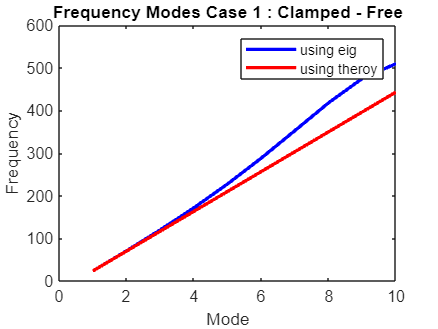


% We notice a difference between theroy and eig from matlab
% We will now plot the diffrence between the two
x = 1:10;
figure;
% Plot the first line in blue
plot(x, wnEig, 'b', 'LineWidth', 2);
hold on;
% Plot the second line in red
plot(x, wnTh, 'r', 'LineWidth', 2);

title("Frequency Modes Case 1 : Clamped - Free");
xlabel('Mode');
ylabel('Frequency');
legend('using eig', 'using theroy');

hold off;

**Conlcusion :**

- We adapted the matrix by removing first degree of freedom

- We made the computations of 10 natural frequancies using eigs(K,M)

- We did the same using therocal formula (10)

- We ploted both to show the delta between the two

- Everything went well, we can move on tot he final case

%CASE 2 : free-free rod

% solve for w, natural frequencies of the bars.
% USING EIG from MATLAB:

[u,wnDiag] = eig(K,M);
wnDiag = wnDiag(2:end,2:end); %we remove first one (-0)
wnEig = sqrt(diag(wnDiag));
disp("Case 2 : Natural frequencies using eig()");

Case 2 : Natural frequencies using eig()


disp(wnEig');

   46.8099   94.7763  145.0698  198.8381  257.0185  319.8029  385.4117  447.9690  495.7221  514.0370




% USING THERORY :

%(...)

% We go through k = 1  to 10 to computute 10 first mode
wnTh = [0 0 0 0 0 0 0 0 0 0];
for k = 1:10; % boucle sur les modes de fréquences
    wnTh(k) = (c0/L)*k*pi;
end

disp("Case 2 : Natural frequencies using therory");

Case 2 : Natural frequencies using therory


disp(wnTh);

   46.6180   93.2360  139.8540  186.4720  233.0900  279.7080  326.3260  372.9440  419.5620  466.1800



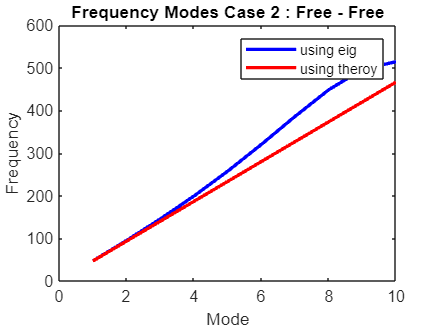


%Once again we have similar resuts but a delta seems to appear
%We plot it


x = 1:10;
figure;
% Plot the first line in blue
plot(x, wnEig, 'b', 'LineWidth', 2);
hold on;
% Plot the second line in red
plot(x, wnTh, 'r', 'LineWidth', 2);

title("Frequency Modes Case 2 : Free - Free")
xlabel('Mode');
ylabel('Frequency');
legend('using eig', 'using theroy');

hold off;

**Conlcusion :**

- We used matrix WITH first degree of freedom

- We made the computations of 10 natural frequancies using eigs(K,M)

- We did the same using therocal formula (10)

- We ploted both to show the delta between the two

- Everything went just like in case 1 except the frequencies are not the same.

% md [3 0; 0 3] VS mc [2 1 ; 1 2]

%We now want to compare those solutions using the diagonal mass matrix Md
%computed at the beginning of this file

% To do so, we redo the second case using Md

[u,wnDiagD] = eig(K,Md);
wnDiagD = wnDiagD(2:end,2:end); %we remove first one (-0)
wnEigD = sqrt(diag(wnDiagD));
disp("Case 2 BIS : Natural frequencies using eig() and Md diagonal mass matrix");

Case 2 BIS : Natural frequencies using eig() and Md diagonal mass matrix


disp(wnEigD');

   46.4265   91.7099  134.7350  174.4426  209.8547  240.0996  264.4324  282.2540  293.1256  296.7794



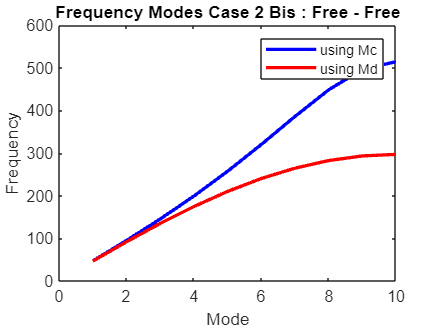


% Now we compare The first results (that we got earlier doing the second case
%) and the brand new results using a diagonal mass matrix.

x = 1:10;
figure;
% Plot the first line in blue
plot(x, wnEig, 'b', 'LineWidth', 2);
hold on;
% Plot the second line in red
plot(x, wnEigD, 'r', 'LineWidth', 2);

title("Frequency Modes Case 2 Bis : Free - Free")
xlabel('Mode');
ylabel('Frequency');
legend('using Mc', 'using Md');

hold off;


%We observe a big delta comming, almost a factor 2 towards the mode k=10 !

**Note : Please execute the code sections in the right order for tyhis to work**

**Conlcusion :**

- We re-computed de second case using Md, the diagonal matrix

- We ploted our old and our new natural frequancies toi compare

- We saw a big difference. Better use Mc in the future !